# Surface reflectance properties

#sec-lightfield-properties

Show the basis functions for surface reflectances.  Then calculate the product of some daylights and surfaces to illustrate the variation in the incident light field with changes in ambient illumination.

Use the Mike Vrhel data set as the example, though perhaps the USGS data set too for materials?

Any chance we can find some standard functions for BRDFs and specular reflection that include both angle and wavelength?

imgdir = '~/Documents/FISE-git/chapters/images/lightfields';
wave = 400:1:700;

## Typical reflectance functions

These are samples of clothing, but many other types of objects have smooth spectral reflectance functions, too.

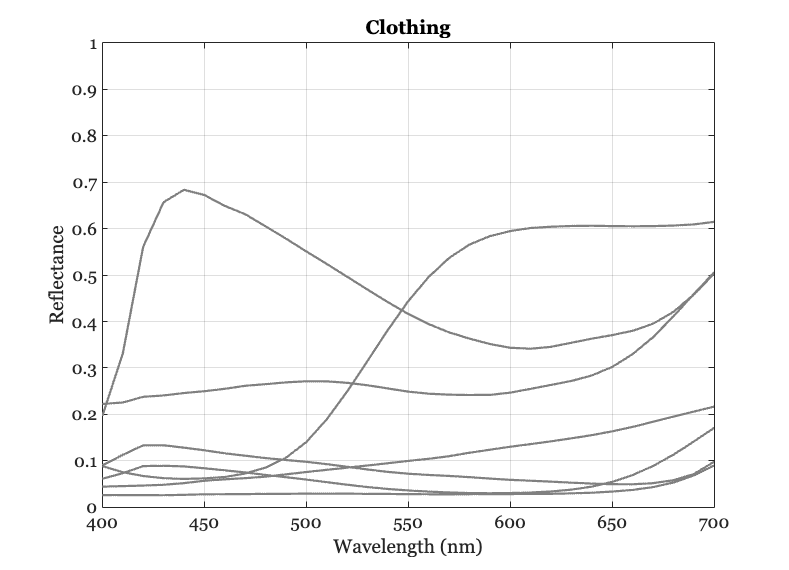

[clothes,~,comment] = ieReadSpectra('Clothes_Vhrel',wave);
plotReflectance(wave,clothes(:,1:6:end),...
    'Color',[0.5 0.5 0.5], ...
    'title','Clothing');
set(gca,'ylim',[0 1]);

%{
exportgraphics(gca,fullfile(imgdir,'01-reflectance-clothes.png'),...
    'Resolution',150);
%}

## Sample linear models

We can compare the linear models from different groups of surfaces. Even though these are wildly different materials, the first three basis functions we would choose for a linear model share many similarities.  

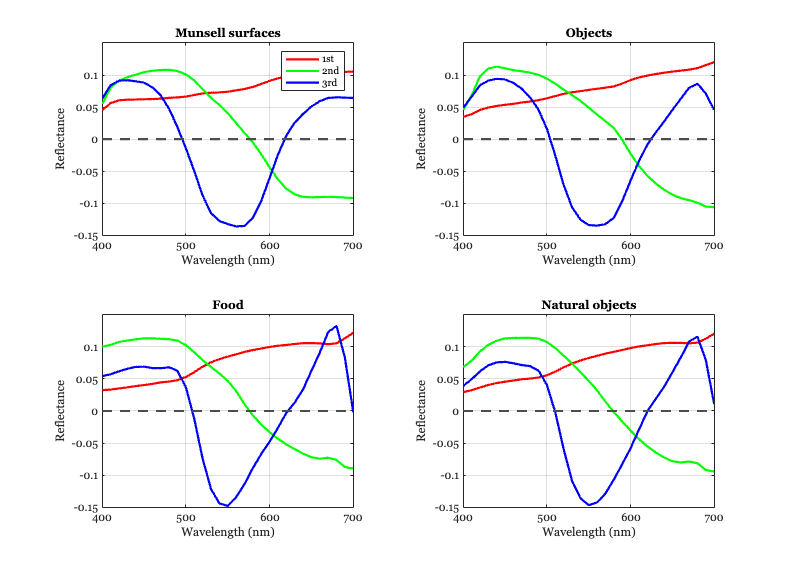

% Should we have a normalized wave option for this method?
wave = 400:2:700;
munsell = ieReadSpectra('MunsellSamples_Vhrel',wave);
nature  = ieReadSpectra('Nature_Vhrel',wave);
objects = ieReadSpectra('Objects_Vhrel',wave);
food    = ieReadSpectra('Food_Vhrel',wave);

[Um, Sm, ~] = svd(munsell,'econ');
[Un, Sn, ~] = svd(nature,'econ');
[Uo, So, ~] = svd(objects,'econ');
[Uf, Sf, ~] = svd(food,'econ');

ylim = [-0.15,0.15]; xlim = [400 700];
hdl = ieFigure; 
tiledlayout(2,2);
nexttile;
plotReflectance(wave,Um(:,1:3)*diag([-1,1,1]),'hdl',hdl, 'title','Munsell surfaces'); hold on;
xaxisLine; set(gca,'ylim',ylim,'xlim',xlim); 
legend({'1st','2nd','3rd'});

nexttile;
plotReflectance(wave,Uo(:,1:3)*diag([-1,-1,-1]),'hdl',hdl, 'title','Objects'); hold on;
xaxisLine; set(gca,'ylim',ylim,'xlim',xlim); 

nexttile;
plotReflectance(wave,Uf(:,1:3)*diag([-1,-1,1]),'hdl',hdl, 'title','Food'); hold on;
xaxisLine; set(gca,'ylim',ylim,'xlim',xlim); 

nexttile
plotReflectance(wave,Un(:,1:3)*diag([-1,1,1]),'hdl',hdl,'title','Natural objects'); hold on;
xaxisLine; set(gca,'ylim',ylim,'xlim',xlim);


%{
set(gcf,'Units','pixels');
set(gcf,'Position',[131   661   956   643]);
exportgraphics(gcf,fullfile(imgdir,'01-reflectance-bases.png'),...
    'Resolution',150); set(gcf,'Units','normalized');
%}

### See whether the bases are close to a linear transformation

Um=Un*T

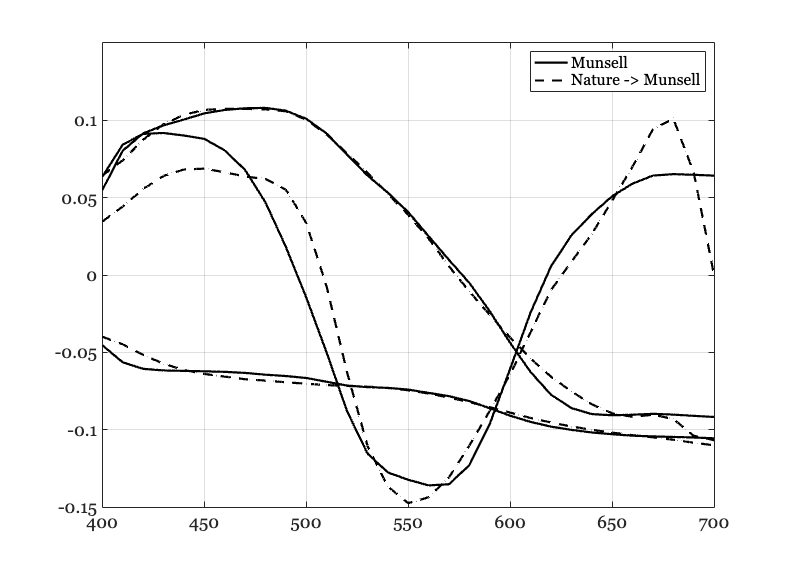

T = pinv(Un(:,1:3))*Um(:,1:3);
UmEst = Un(:,1:3)*T;

ieFigure;
hA = plot(wave,Um(:,1:3),'k-','LineWidth',2); hold on;
hB = plot(wave,UmEst,'k--','LineWidth',2); hold on;
legend([hA(1) hB(1)],{'Munsell','Nature -> Munsell'});
set(gca,'ylim',ylim,'xlim',xlim);
grid on;

%{
exportgraphics(gca,fullfile(imgdir,'01-reflectance-basis-match.png'),...
    'Resolution',150);
%}


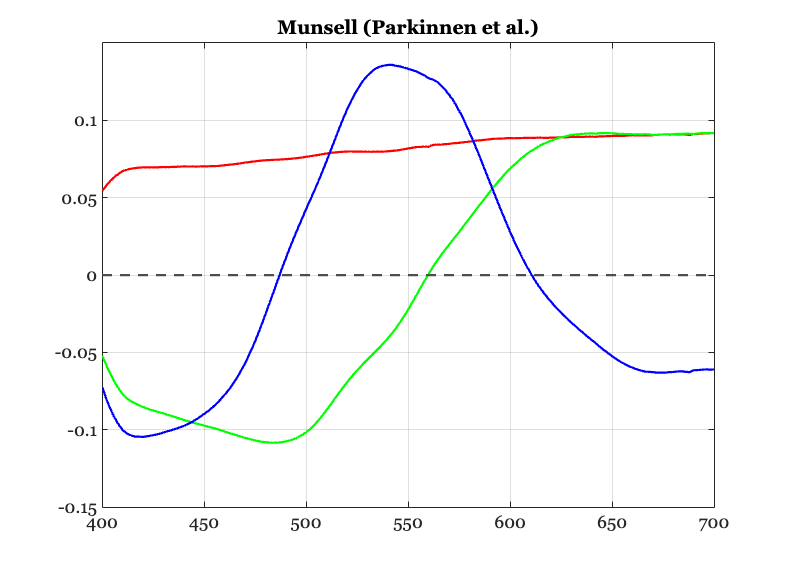

munsell = ieReadSpectra('munsell_matte',wave); 
[U,S,V] = svd(munsell,'econ');
ieFigure;
plot(wave,U(:,1:3),'LineWidth',2); 
grid on; 
set(gca,'ylim',ylim,'xlim',xlim); xaxisLine;
grid on; xaxisLine; title('Munsell (Parkinnen et al.)')